**ECE675 HW3 Problem 2:**

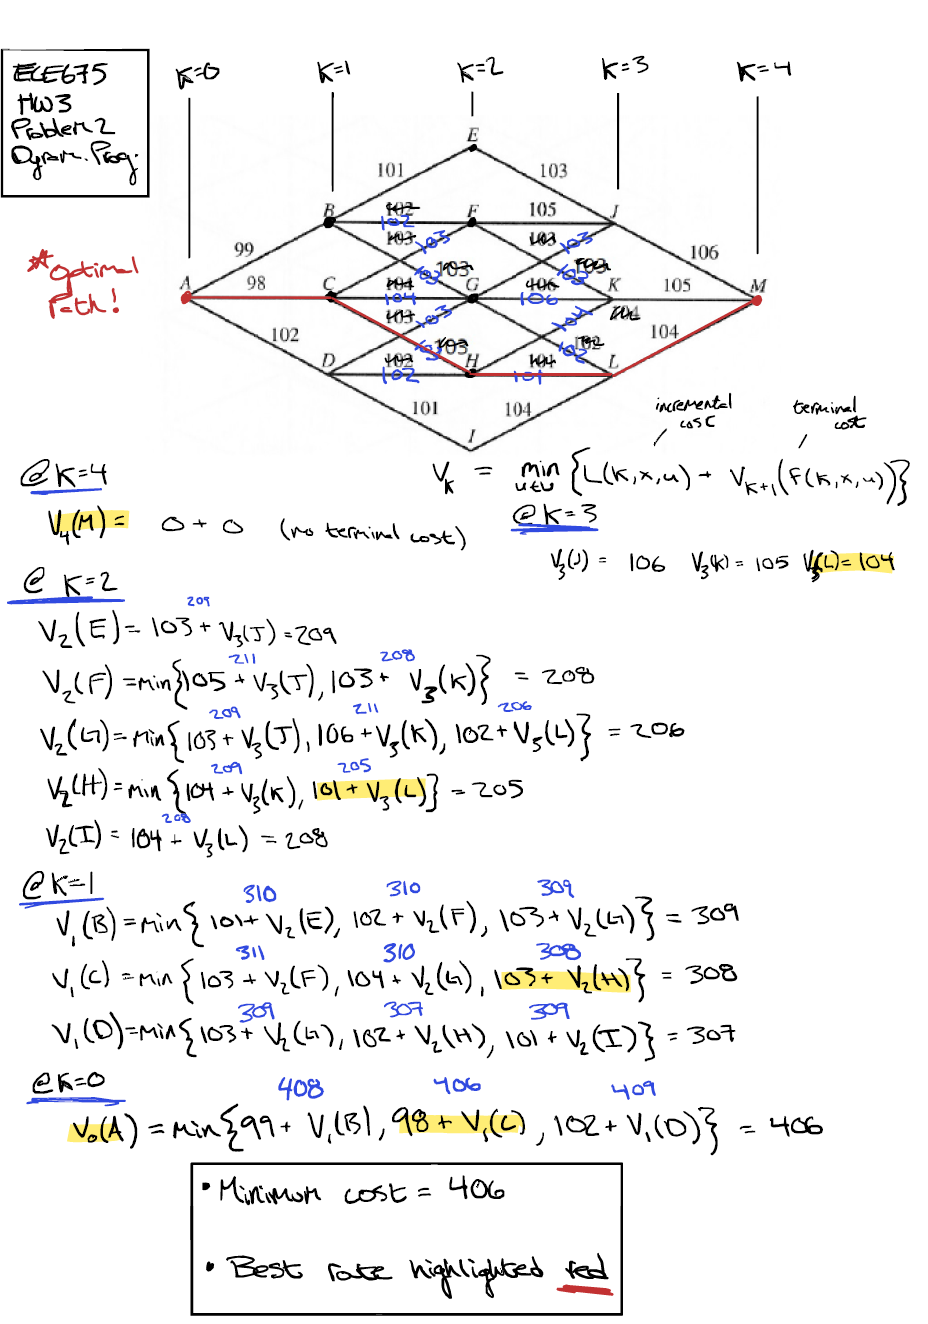

**ECE675 HW3 Problem 3:**

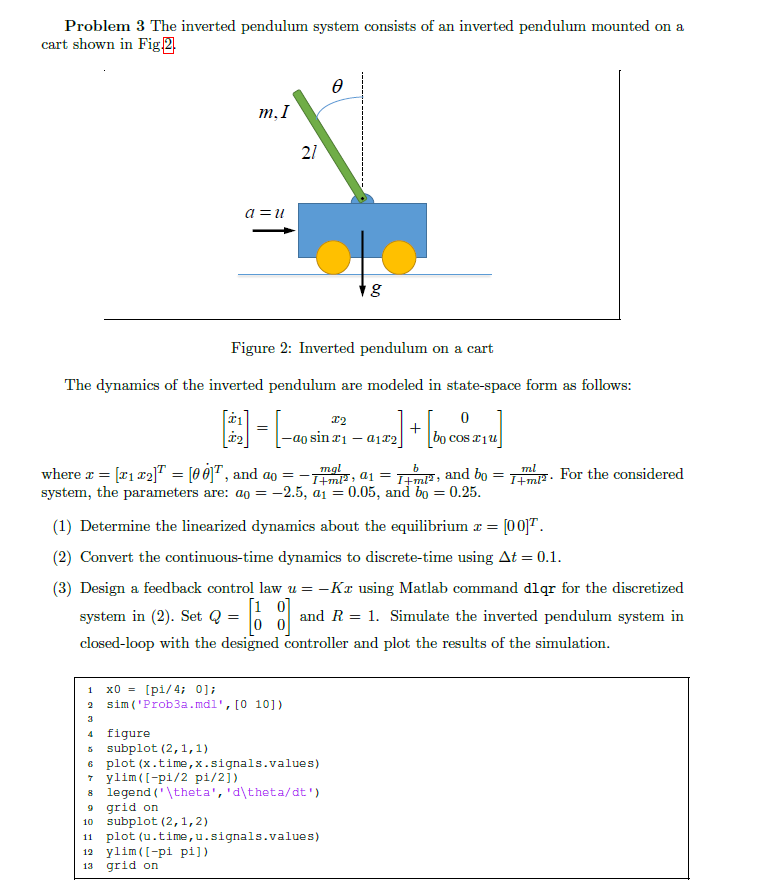

**Problem 3.1: Linearized Dynamics**

syms a0 a1 b0 x1 x2

% Linearize at x = [0; 0], cos(x1) --> 1, sin(x1) --> x1
A_lin = [0, 1; -a0, -a1]

$$A\_lin = \left(\begin{array}{cc} 0 & 1\\ -a_{0} & -a_{1} \end{array}\right)$$

B_lin = [0; b0]

$$B\_lin = \left(\begin{array}{c} 0\\ b_{0} \end{array}\right)$$


% Substitute in the numerical given values:
A_lin = double(subs(A_lin,[a0,a1,b0],[-2.5,0.05,0.25]))

A_lin =          0    1.0000
    2.5000   -0.0500


B_lin = double(subs(B_lin,[a0,a1,b0],[-2.5,0.05,0.25]))

B_lin =          0
    0.2500


**Problem 3.2: Discretize the Dynamics:**

% Sample Rate
ts = 0.1;
% Intitial Cond.
x0 = [pi/4; 0];

% Define continuous system, build discrete ss system
ContLinSystem = ss(A_lin,B_lin,zeros(2,2),zeros(2,1))


ContLinSystem =
 
  A = 
          x1     x2
   x1      0      1
   x2    2.5  -0.05
 
  B = 
         u1
   x1     0
   x2  0.25
 
  C = 
       x1  x2
   y1   0   0
   y2   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


DiscLinSystem = c2d(ContLinSystem,ts);

% Extract A & B for discrete system
Ad_lin = DiscLinSystem.A

Ad_lin =     1.0125    0.1002
    0.2504    1.0075


Bd_lin = DiscLinSystem.B

Bd_lin =     0.0013
    0.0250


Cd_lin = eye(2,2)

Cd_lin =      1     0
     0     1


Dd_lin = DiscLinSystem.D

Dd_lin =      0
     0


**Problem 3.3: Discrete LQR Controller**

Q = [1 0; 0 0];
R = 1;

[K_dlqr, S, P] = dlqr(Ad_lin,Bd_lin,Q,R)

K_dlqr =    18.5997   11.5669


S = 1.0e+03 *

    1.2961    0.8036
    0.8036    0.4997


P =    0.8535 + 0.0064i
   0.8535 - 0.0064i



simout1 = sim('ECE675_HW3_Problem3_sim.mdl',[0 10])

simout1 =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [101x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


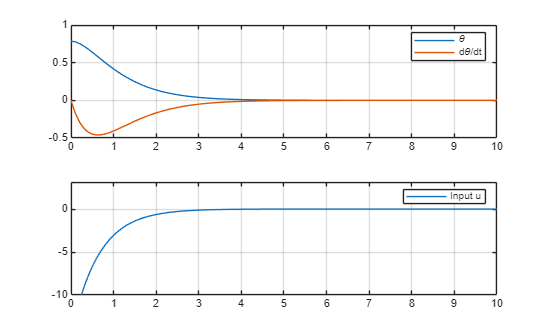


theta = simout1.logsout{1}.Values.Data(:,1);
theta_dot = simout1.logsout{1}.Values.Data(:,2);
time = simout1.logsout{1}.Values.Time(:,1);
input = simout1.logsout{2}.Values.Data(:,1);

figure
subplot(2,1,1)
plot(time,theta)
hold on
plot(time, theta_dot)
legend('\theta','d\theta/dt')
grid on
subplot(2,1,2)
plot(time, input)
ylim([-10,pi])
legend('Input u')
grid on

**Problem 3.4: Discrete LQR Controller**

% Play with these params
% parameters
X1GridSize = 10;
X2GridSize = X1GridSize;
N = 20;                     % DP horizon
Q = [1 0; 0 0];
R = 1;

% stage + terminal cost
Jstage = @(x,u) x'*Q*x + u'*R*u;
Jtogo  = @(x) x'*Q*x;       % initial terminal cost

% grid state-space
X1 = linspace(-pi/2, pi/2, X1GridSize);
X2 = linspace(-pi/2, pi/2, X2GridSize);

% allocate
U = zeros(X1GridSize, X2GridSize);
J = zeros(X1GridSize, X2GridSize);

% fminunc options
opts = optimoptions('fminunc','Display','off');

for n = 1:N
    for i = 1:length(X1)
        for j = 1:length(X2)

            x = [X1(i); X2(j)];

            % cost-to-go minimization
            costfun = @(u) Jstage(x,u) + Jtogo(Ad_lin*x + Bd_lin*u);

            [U(i,j), J(i,j)] = fminunc(costfun, 0, opts);

        end
    end

    % update cost-to-go
    % interp2 ORDER: (X2, X1, Table, x2, x1)
    Jtogo = @(x) interp2(X2, X1, J, x(2), x(1), 'spline');
end

function u = GetInput(x_state, X1, X2, U)
    x1 = x_state(1);
    x2 = x_state(2);

    % interp2 order: (X2grid, X1grid, Table, x2, x1)
    u = interp2(X2, X1, U, x2, x1, 'linear');

    % clamp if outside grid (interp2 returns NaN)
    if isnan(u)
        x1c = min(max(x1, min(X1)), max(X1));
        x2c = min(max(x2, min(X2)), max(X2));
        u = interp2(X2, X1, U, x2c, x1c, 'linear');
    end
end
% Anonymous function interpolates the best input u from the
% DP grid U and returns it. Call this @ every time step
GetOptimalInput = @(x_state) GetInput(x_state, X1, X2, U)

GetOptimalInput = function_handle with value:
    @(x_state)GetInput(x_state,X1,X2,U)


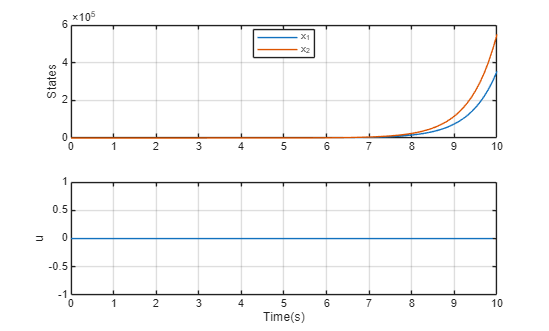

% Simulate using DP controller for 10 seconds closed loop
Tfinal = 10;
ts = 0.1;
timesteps = round(Tfinal/ts);

% Initialize state and input logging, plot later
Xlog = zeros(2, Nsteps+1);
Ulog = zeros(1, Nsteps);
t = (0:timesteps)*ts;
x_cl_DP = [x0, zeros(2,timesteps-1)];
u_cl_DP = [0, zeros(1,timesteps-1)];

for k = 1:timesteps

    % control law from DP lookup
    currentState = x_cl_DP(:,k);
    u_cl_DP(:,k) = GetOptimalInput(currentState);

    % discrete system dynamics
    x_cl_DP(:,k+1) = Ad_lin*x_cl_DP(:,k) + Bd_lin*u_cl_DP(:,k);
end

% States
figure;
subplot(2,1,1)
plot(t, x_cl_DP(1,:));
hold on
plot(t, x_cl_DP(2,:))
grid on
legend('x_1','x_2','Location','Best')
ylabel('States')

% Input
subplot(2,1,2)
plot(t(1:end-1), Ulog)
grid on
ylabel('u')
xlabel('Time(s)')

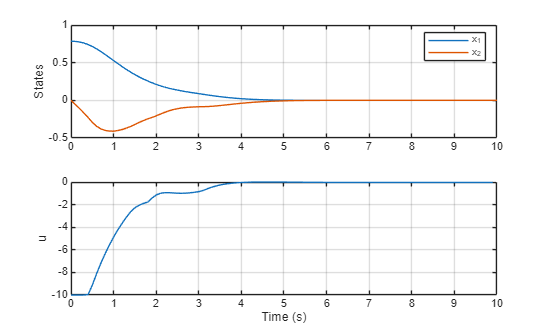


% Get discrete LQR terminal cost matrix using dlqr (you already computed)
% [K_dlqr, S, ~] = dlqr(Ad_lin,Bd_lin,Q,R);   % S is solution of discrete riccati (use your existing S)

% params
X1GridSize = 20;
X2GridSize = X1GridSize;
DP_horizon = 20;

% stage + terminal cost
Jstage = @(x,u) x'*Q*x + u'*R*u;
Jtogo = @(x) x'*S*x;      % use Riccati solution as terminal cost — much better boundary

% state grid
X1 = linspace(-pi/2, pi/2, X1GridSize);
X2 = linspace(-pi/2, pi/2, X2GridSize);

% allocate tables
U = zeros(X1GridSize, X2GridSize);
J  = zeros(X1GridSize, X2GridSize);

% bounded u search grid (robust alternative to fminunc)
umax = 10;                % choose reasonable control bounds
u_grid = linspace(-umax, umax, 201);

% Value iteration
for iter = 1:DP_horizon
    for i = 1:length(X1)
        for j = 1:length(X2)
            x = [X1(i); X2(j)];

            % evaluate cost for every u candidate
            % next state
            Xnext = Ad_lin*x + Bd_lin * u_grid;   % 2 x numU
            % compute cost: stage + terminal-on-next
            cost_vals = zeros(size(u_grid));
            for m = 1:numel(u_grid)
                xn = Xnext(:,m);
                % evaluate Jtogo at xn via interp2 on J table (if iter>1)
                if iter==1
                    future_cost = Jtogo(xn);  % currently x'*S*x
                else
                    % safe interp: clamp xn to grid before interp
                    x1c = min(max(xn(1), min(X1)), max(X1));
                    x2c = min(max(xn(2), min(X2)), max(X2));
                    future_cost = interp2(X2, X1, J, x2c, x1c, 'linear');
                end
                cost_vals(m) = Jstage(x, u_grid(m)) + future_cost;
            end

            % pick best u
            [mincost, midx] = min(cost_vals);
            U(i,j) = u_grid(midx);
            J(i,j) = mincost;
        end
    end

    % update Jtogo to the just-computed J table
    % NOTE: J is arranged as J(i over X1, j over X2)
    Jtogo = @(xq) interp2(X2, X1, J, ...
                         min(max(xq(2), min(X2)), max(X2)), ...
                         min(max(xq(1), min(X1)), max(X1)), 'linear');
end

% DP policy accessor (with clamping)
function u = GetInput_DP(x_state, X1, X2, U)
    x1 = x_state(1);
    x2 = x_state(2);
    % clamp
    x1c = min(max(x1, min(X1)), max(X1));
    x2c = min(max(x2, min(X2)), max(X2));
    u = interp2(X2, X1, U, x2c, x1c, 'linear');
end

GetOptimalInput = @(x_state) GetInput_DP(x_state, X1, X2, U);

%% === Simulate closed-loop with DP policy ===
Tfinal = 10;
timesteps = round(Tfinal/ts);

x_cl_DP = zeros(2, timesteps+1);
u_cl_DP = zeros(1, timesteps);

x_cl_DP(:,1) = x0;

for k = 1:timesteps
    curx = x_cl_DP(:,k);
    u = GetOptimalInput(curx);
    u_cl_DP(k) = u;
    x_cl_DP(:,k+1) = Ad_lin*curx + Bd_lin*u;
end

t = 0:ts:Tfinal;

% plots
figure;
subplot(2,1,1)
plot(t, x_cl_DP(1,:), t, x_cl_DP(2,:))
grid on
legend('x_1','x_2')
ylabel('States')

subplot(2,1,2)
plot(t(1:end-1), u_cl_DP)
grid on
ylabel('u')
xlabel('Time (s)')